1b)

clear all; close all; clc; clf;
mu = 5;
sigma =1;
pd = makedist('Normal','mu',mu,'sigma',sigma)

pd =   NormalDistribution

  Normal distribution
       mu = 5
    sigma = 1


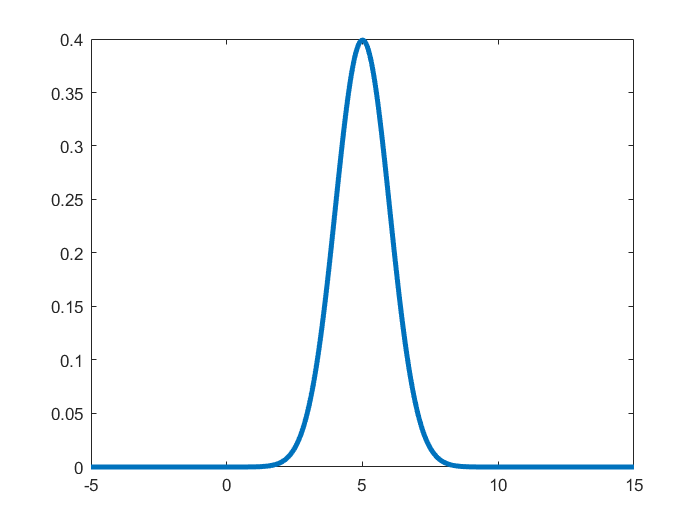

x = linspace(-5,15,1000);
plot(x,pdf(pd,x),"LineWidth",3);

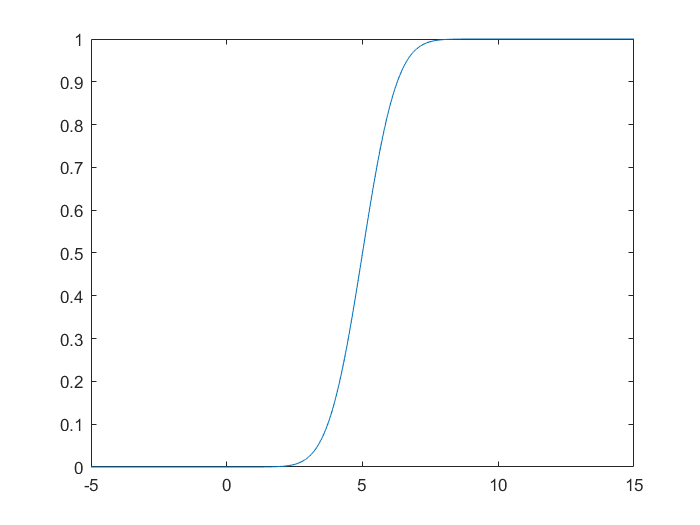

plot(x, normcdf(x,mu,sigma));

1c) 

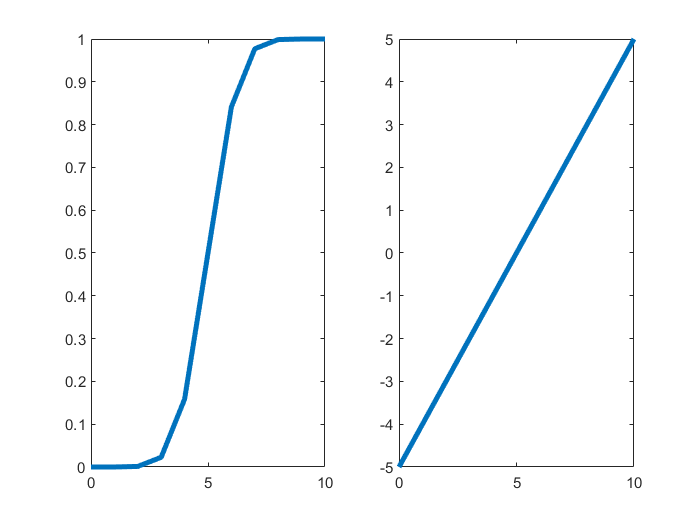

subplot(1,2,1)
plot(x, normcdf(x,mu,sigma),"LineWidth",3); %cumulative distribution
subplot(1,2,2)
plot(x, norminv(normcdf(x,mu,sigma)),"LineWidth",3) %Sigma values

1d) 

    Negative sigma values make sense because the values to the left of the mean are smalller than the mean and sigma is the standard deviation.

2a)

    The Chi-Squared distribution is a distribution of independent random variables with a normal distribution. The Chi-Squared statistic is often used to determine the independence of two sets of data.

2b) 

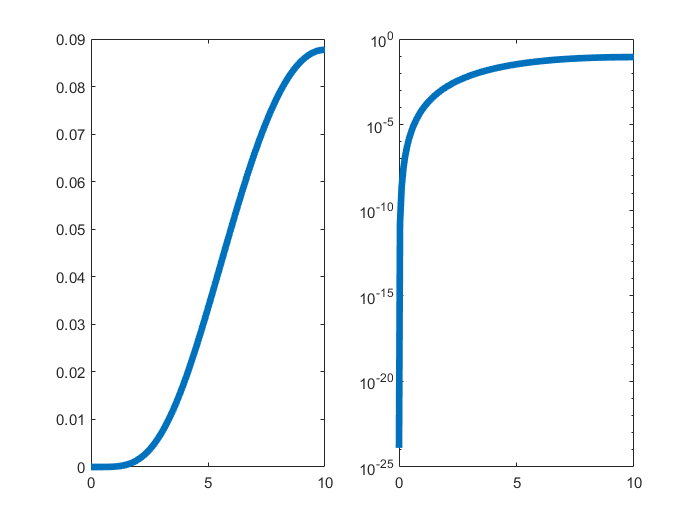

clf
x = linspace(0,10,100000);
chisq = makedist("Gamma",'a',12/2.,'b',2); %special case for Chi-squared
subplot(1,2,2)
plot(x,pdf(chisq,x),"LineWidth",4);
set(gca,'YScale','log')

subplot(1,2,1) 
plot(x,pdf(chisq,x),"LineWidth",4);

3a/b)

    How many values in my distribution are less than 4.

3c)


$$\int_{0}^{4}{f_n(x) dx$$


3d/e)

p = cdf(chisq,4) %sigma equivalent

p = 0.0166

numberOfValues = p*100000

numberOfValues = 1.6564e+03

4)

p = cdf(chisq,50) %sigma equivalent

p = 1.0000

numberOfValues = p*100000

numberOfValues = 1.0000e+05

Sigma equivalent p increases with the measurement value until p hits a value of 1, at which point, all 100,000 data points are less than the value given to it and as the measurement value increases further, p remains 1.

Non-continous distributions

1a) Poisson distribution

1b)

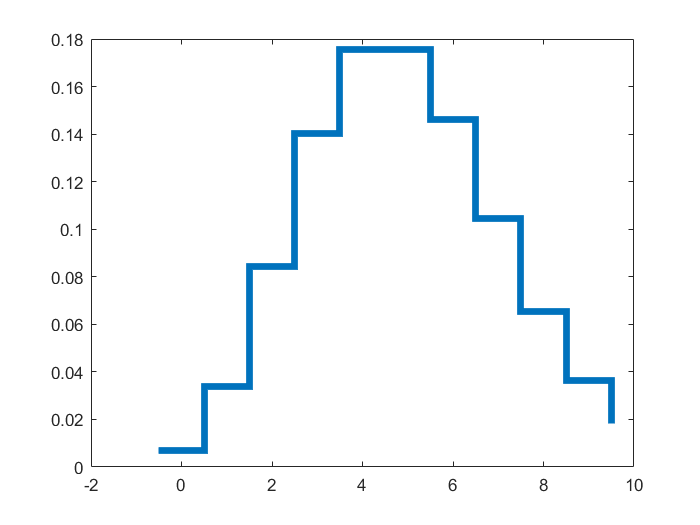

clf;
x = 0:10;
poisson = makedist("Poisson", 'lambda',5); 
%nu=1 makes a lorentz distribution as a special case
stairs(x-0.5,pdf(poisson,x),"LineWidth",4);

Lambda seems to vary the distribution of the plot with lower lambda values making the distribution more concentrated on the left and higher lambda values making the distribution more concentrated on the right side.

1c)

    When lambda = 5, what is the chance of a random value from my distribution being less than 5?

p = cdf(poisson,5) %sigma equivalent

p = 0.6160

1d)

    The implication of discrete values have for an expirement is that you cannot have 1.6 people, you can only have one person or two people. Because of this however, discrete distributions make sense for certain kinds of studies (i.e. how much of a population contains a certain genetic mutation). Certain statistical values of a discrete distribution are not discreet however (i.e. the mean), however this makes sense because the mean by definition is the sum of all the values (which is a continous measurement) divided by the number of values which is inherently almost always a non-integered value.